% clear;clf;
% [X,Y] = meshgrid(0:0.01:0.99);
% f_ori = @(x,y,focal)(1./sqrt(x.^2+y.^2+focal^2));
% Z = 1./sqrt(X.^2+Y.^2+1);
% % Z = f_ori(X,Y,1);
% figure;
% mesh(X,Y,Z)
% % hold on
% view([65.605 32.885])

clear;clf;

focal_length = 1;
f_ori = @(x,y)(1./sqrt(x.^2+y.^2+(focal_length)^2));

% 步长和子块大小
step = 2^-10;
block_size = 1/16;
def_domain = 1;

% 创建网格点
[X, Y] = meshgrid(0:step:def_domain-step);

% 初始化查找表
slopeX_lookup = zeros(floor(def_domain/block_size), floor(def_domain/block_size));
slopeY_lookup = zeros(floor(def_domain/block_size), floor(def_domain/block_size));
intercept_lookup = zeros(floor(def_domain/block_size), floor(def_domain/block_size));

% 计算每个子块上的梯度和截距
for i = 1:floor(def_domain/block_size)
    for j = 1:floor(def_domain/block_size)
        % 子块的边界
        x_block_min = (i-1) * block_size;
        x_block_max = i * block_size;
        y_block_min = (j-1) * block_size;
        y_block_max = j * block_size;
        
        % 子块中的采样点
        x_samples = linspace(x_block_min, x_block_max, 256);
        y_samples = linspace(y_block_min, y_block_max, 256);
        [X_samples, Y_samples] = meshgrid(x_samples,y_samples);
        
        % 计算二次插值拟合
%         Z_samples = 1./sqrt(X_samples.^2 + Y_samples.^2 + 1);
        Z_samples = f_ori(X_samples,Y_samples);

        func = @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)
        fX = [X_samples(:), Y_samples(:)];
        fZ = Z_samples(:);
        p = lsqcurvefit(func, rand(1,3), fX, fZ);
        
        % 存储梯度和截距到查找表
        slopeX_lookup(i, j) = p(1);
        slopeY_lookup(i, j) = p(2);
        intercept_lookup(i, j) = p(3);
    end
end

func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


func = 包含以下值的 function_handle :
    @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


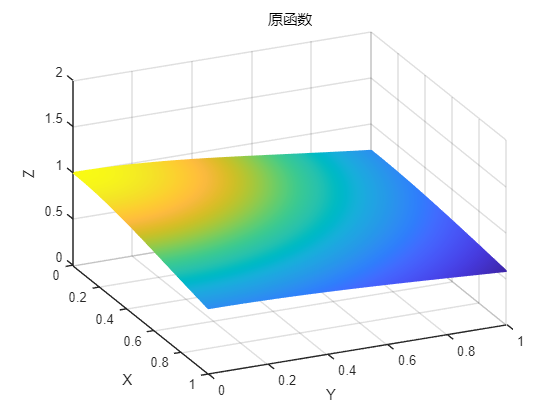


% 使用查找表近似计算 Z
Z_approx = zeros(size(X));
for i = 1:numel(X)
    % 获取当前位置所在子块的索引
    x_block_index = floor(X(i) / block_size) + 1;
    y_block_index = floor(Y(i) / block_size) + 1;
    
    % 获取对应子块的梯度和截距
    slopeX = slopeX_lookup(x_block_index, y_block_index);
    slopeY = slopeY_lookup(x_block_index, y_block_index);
    intercept = intercept_lookup(x_block_index, y_block_index);
    
    % 近似计算 Z
    Z_approx(i) = slopeX * X(i) + slopeY * Y(i) + intercept;
end

% 绘制原函数和近似函数的图像
Z_true = f_ori(X,Y);
figure;
mesh(X, Y, Z_true);
view([65.605 32.885]);
axis([0 def_domain 0 def_domain 0 2]);
title('原函数');
xlabel('X');
ylabel('Y');
zlabel('Z');

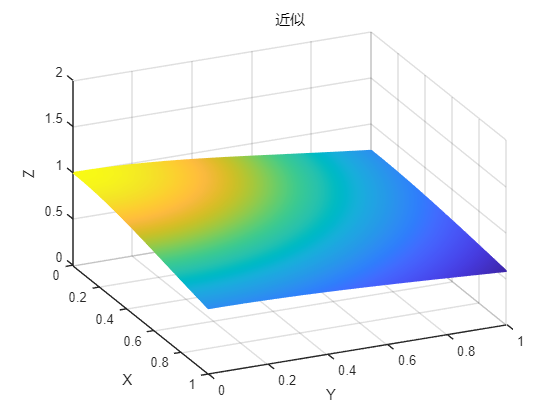


figure;
mesh(X, Y, Z_approx);
view([65.605 32.885]);
axis([0 def_domain 0 def_domain 0 2]);
title('近似');
xlabel('X');
ylabel('Y');
zlabel('Z');


dif = abs(Z_true - Z_approx)./Z_true;
max(dif(:))

ans = 6.4368e-04

% clear;clf;
% x = linspace(0,0.99,100);
% y = linspace(0,0.99,100);
% [X,Y] = meshgrid(x,y);
% Z = 1./sqrt(x.^2 + (y').^2 + 1);
% 
% func = @(a,T)a(1)*T(:,1)+a(2)*T(:,2)+a(3)
% fX = [X(:), Y(:)];
% fZ = Z(:);
% a = lsqcurvefit(func, rand(1,3), fX, fZ)

max(slopeX_lookup(:))

ans = -0.0116

min(slopeY_lookup(:))

ans = -0.3842

max(intercept_lookup(:))

ans = 1.0884

min(intercept_lookup(:))

ans = 0.9742

inv_LUT_x = -slopeX_lookup;
inv_LUT_y = -slopeY_lookup;
LUT_itcpt = intercept_lookup;

log2(max(inv_LUT_x(:)))

ans = -1.3799

log2(max(LUT_itcpt(:)))

ans = 0.1223


fracLXY = 12;
fracLIP = 15;
X_table = ufi(inv_LUT_x, fracLXY-1,fracLXY);
Y_table = ufi(inv_LUT_y, fracLXY-1,fracLXY);
I_table = ufi(LUT_itcpt, fracLIP+1,fracLIP);


Z_approx_quant = zeros(size(X));
for i = 1:numel(X)
    % 获取当前位置所在子块的索引
    x_block_index = floor(X(i) / block_size) + 1;
    y_block_index = floor(Y(i) / block_size) + 1;
    
    % 获取对应子块的梯度和截距
    slopeX = double(X_table(x_block_index, y_block_index));
    slopeY = double(Y_table(x_block_index, y_block_index));
    intercept = double(I_table(x_block_index, y_block_index));
    
    % 近似计算 Z
    Z_approx_quant(i) = -slopeX * X(i) - slopeY * Y(i) + intercept;
end
dif_quant = abs(Z_true - Z_approx_quant)./Z_true;
max(dif_quant(:))

ans = 6.4087e-04


% max(Z_true(:) - Z_approx_quant(:))
% min(Z_true(:) - Z_approx_quant(:))
% sum(Z_true(:) - Z_approx_quant(:))

file_out=fopen("LUT.txt",'w');
ab_length = X_table(1);
c_length = I_table(1);
fprintf(file_out, '//approx func: 1/sqrt(x^2 + y^2 + %s^2), x&y within [0, %s] as: -Ax - By + C\n',...
    num2str(focal_length), num2str(def_domain));
fprintf(file_out, '//C wordlength: %d, fraclength: %d,  B/A wordlength: %d, fraclength: %d\n',...
    c_length.WordLength, c_length.FractionLength, ab_length.WordLength, ab_length.FractionLength);
fprintf(file_out, '//index       C           B         A,    all is unsigned\n');
for iy=1:1/block_size
    for ix=1:1/block_size
        case_value = strcat(dec2bin(iy-1,log2(1/block_size)), dec2bin(ix-1,log2(1/block_size)));
        X_mantissa = X_table(ix,iy);
        Y_mantissa = Y_table(ix,iy);
        I_mantissa = I_table(ix,iy);
        output_value = strcat(I_mantissa.bin," ",Y_mantissa.bin," ",X_mantissa.bin);
        fprintf(file_out, '%s %s\n', case_value,output_value);
    end
end
fclose(file_out);